# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

clear all; close all;

## Loading all the data

collectedElectrodes = ["C3", "Cz", "C4"]; % or just simple string "all"
% collectedElectrodes = "all";

DataSetD = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1d.mat", collectedElectrodes);
DataSetB = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1b.mat", collectedElectrodes);
DataSetC = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1c.mat", collectedElectrodes);
DataSetE = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1e.mat", collectedElectrodes);
DataSetG = EEGDataSet_chunks("../data/hands/BCICIV_calib_ds1g.mat", collectedElectrodes);


Data organization and splitting into training/validation/testing:

tempInputs = [
    DataSetD.EEGToLoad;
    DataSetB.EEGToLoad;
    DataSetC.EEGToLoad;
    DataSetE.EEGToLoad;
    DataSetG.EEGToLoad
    ];

tempOutputs = [
    DataSetD.signalsCueCategoricalOUTPUT;
    DataSetB.signalsCueCategoricalOUTPUT;
    DataSetC.signalsCueCategoricalOUTPUT;
    DataSetE.signalsCueCategoricalOUTPUT;
    DataSetG.signalsCueCategoricalOUTPUT;
    ];

% Filter for strictly equal chunk length:
Inputs = filterHands(tempInputs);
Outputs = filterHands(tempOutputs);


Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets
nChunks=numel(Outputs);
[trainInd,valInd,testInd] = dividerand(nChunks,0.8,0,0.2);
 
InTrain = Inputs(1,trainInd);
OutTrain= Outputs(1,trainInd);
% InValid = Inputs(1,valInd);
% OutValid= Outputs(1,valInd);
InTest  = Inputs(1,testInd);
OutTest= Outputs(1,testInd);


## Define Deep Learning Model

layers = [
    sequenceInputLayer(3,"Name","input")
    lstmLayer(128,"Name","lstm")
    dropoutLayer(0.5,"Name","drop")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

lgraph = layerGraph(layers);

View the network in a plot.

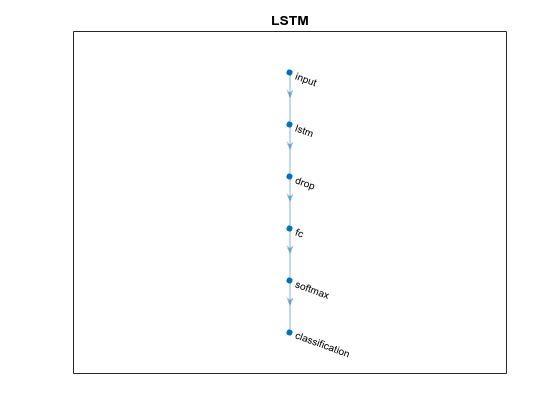

figure
plot(lgraph)
title("LSTM")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

% options = trainingOptions("adam", ...
%     MaxEpochs=200, ...
%     miniBatchSize=20, ...
%     ValidationData={InValid,OutValid}, ...
%     ValidationFrequency=100, ...
%     Plots="training-progress", ...
%     Shuffle="every-epoch", ...
%     Verbose=true);

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    miniBatchSize=20, ...
    Plots="training-progress", ...
    Shuffle="every-epoch", ...
    Verbose=true);

## Train Model

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       48.09% |       0.8871 |          0.0010 |
|       2 |          50 |       00:00:05 |       51.40% |       0.7778 |          0.0010 |
|       3 |         100 |       00:00:07 |       50.64% |       0.7494 |          0.0010 |
|       5 |         150 |       00:00:08 |       54.47% |       0.7078 |          0.0010 |
|       6 |         200 |       00:00:10 |       53.29% |       0.7085 |          0.0010 |
|       8 |         250 |       00:00:12 |       50.51% |       0.7182 |          0.0010 |
|       9 |         300 |       00:00:14 |       48.57% |       0.

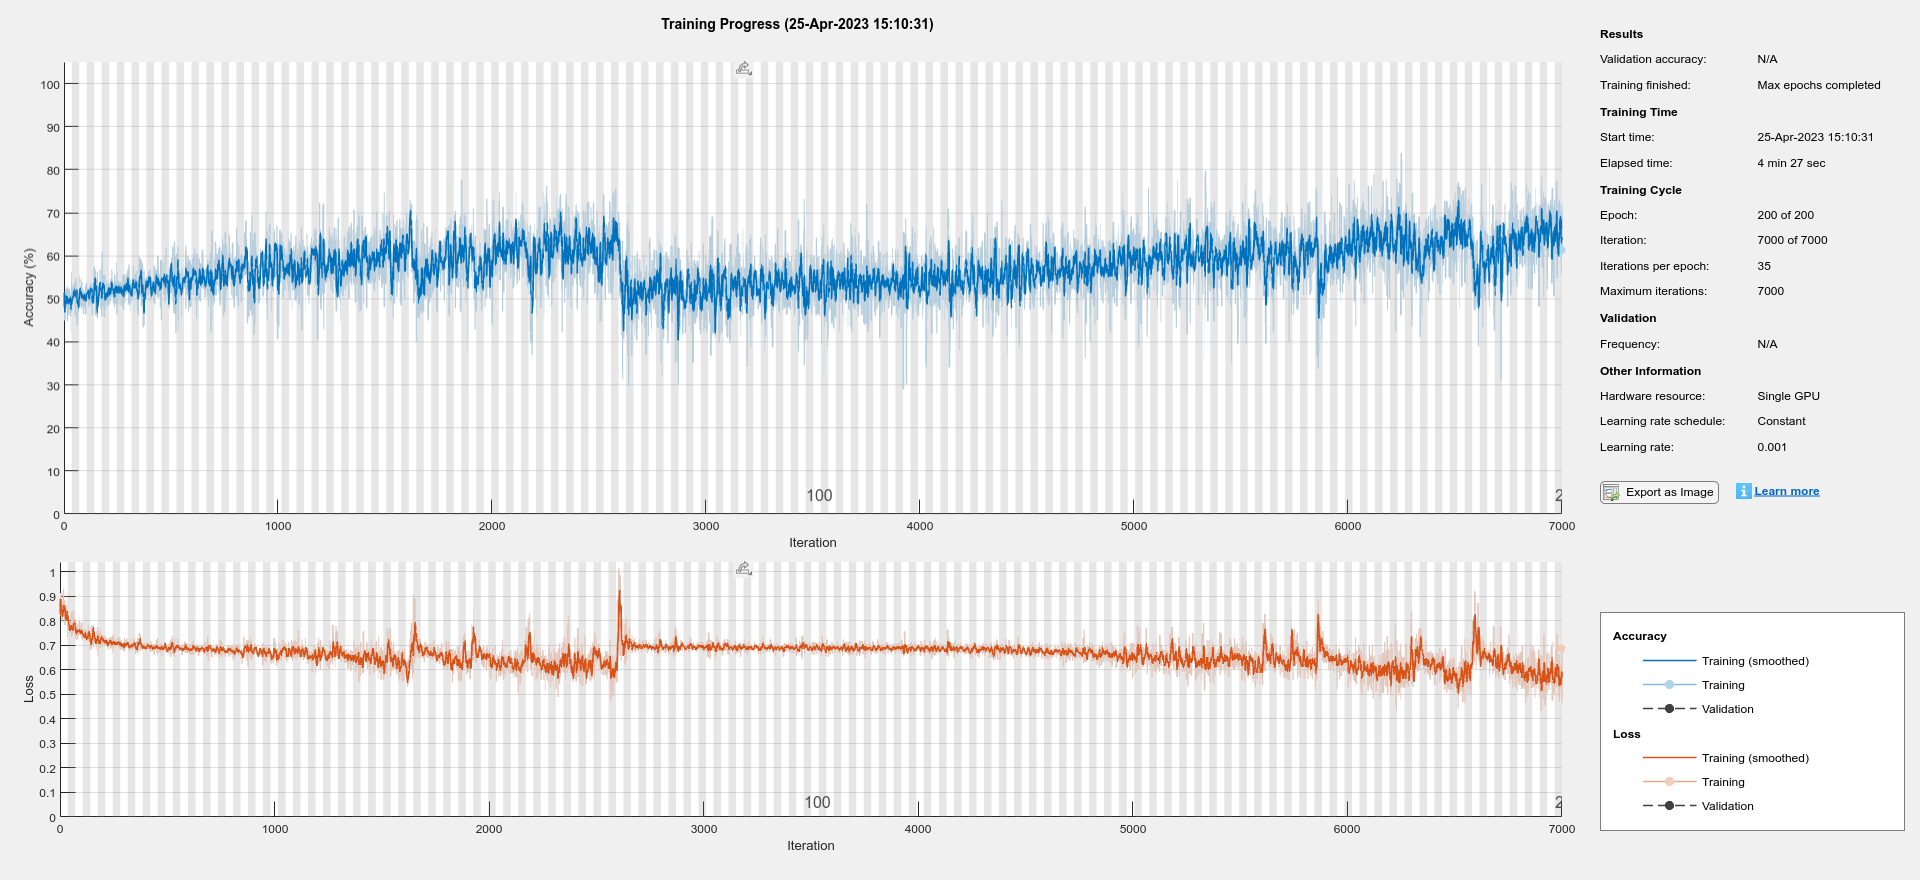

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       74.11% |       0.4763 |          0.0010 |
|       2 |          50 |       00:00:03 |       67.56% |       0.5258 |          0.0010 |
|       3 |         100 |       00:00:05 |       63.24% |       0.6191 |          0.0010 |
|       5 |         150 |       00:00:07 |       50.12% |       0.7540 |          0.0010 |
|       6 |         200 |       00:00:08 |       55.90% |       0.6727 |          0.0010 |
|       8 |         250 |       00:00:10 |       62.04% |       0.6278 |          0.0010 |
|       9 |         300 |       00:00:12 |       64.72% |       0.

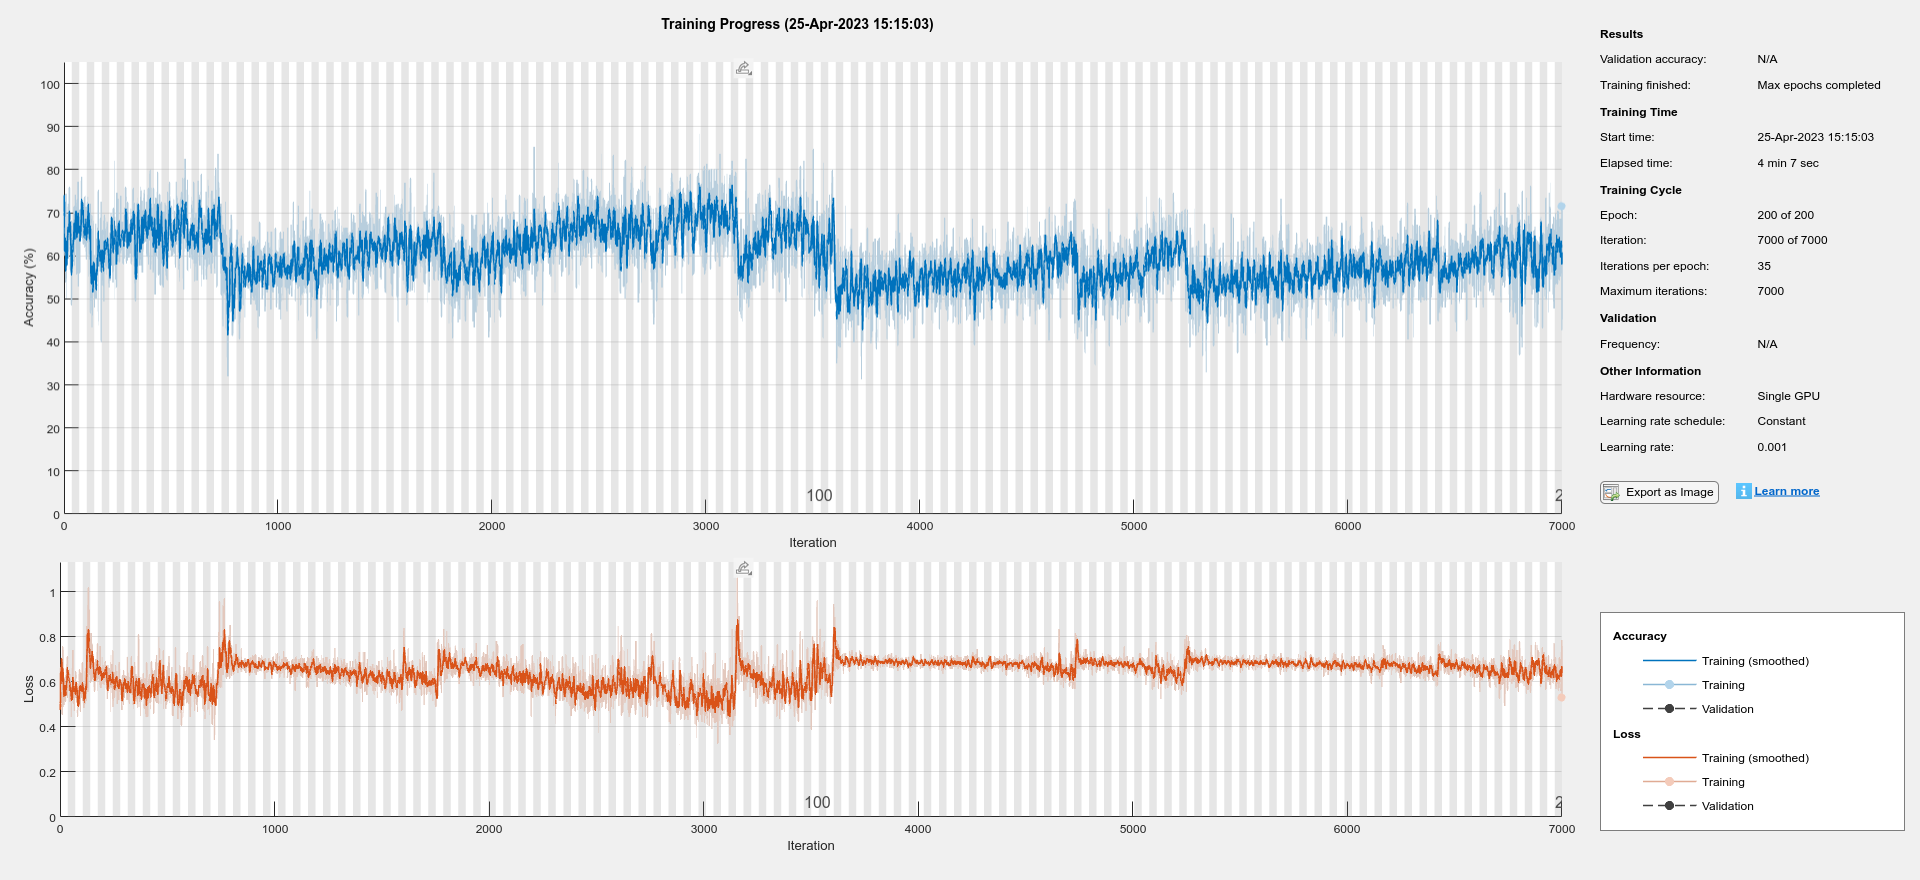

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);

Visualize the predictions for **each sample** in a confusion matrix.

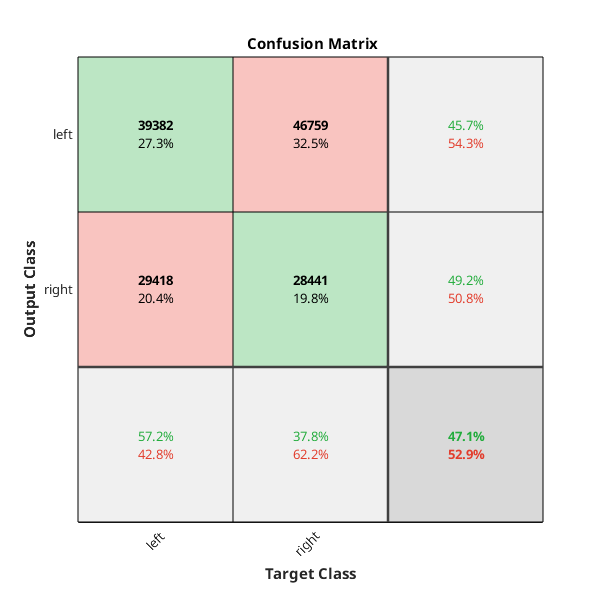

Pred = vertcat(OutPred{:});
True = vertcat(OutTest{:});
plotconfusion(True(:),Pred(:));

Visualize the predictions for **each sample** in a confusion matrix.

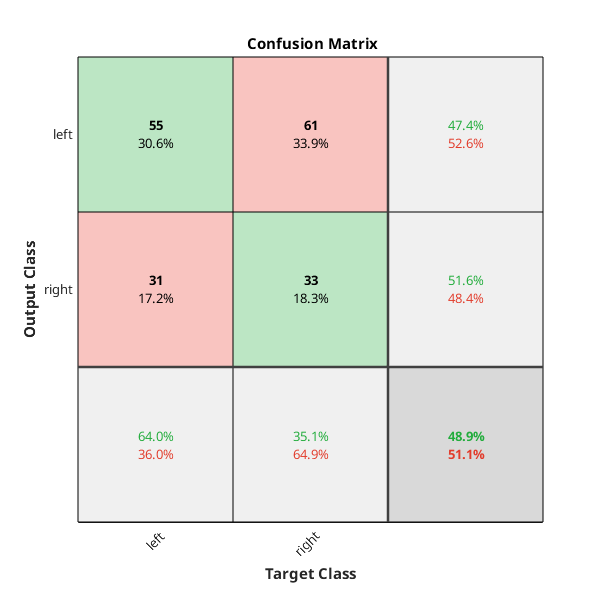

Pred = vertcat(OutPred{:});
True = vertcat(OutTest{:});
PredCount = countcats(Pred');
Predictions=1*(PredCount(1,:)<PredCount(2,:));
PredChunk = categorical(Predictions,[0 1],{'left', 'right'});
TrueChunk = True(:,1);
plotconfusion(TrueChunk(:),PredChunk(:));